## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 11 - Example 05 - Miura Origami and Bar and Hinge Models**

In this example, we will try to simulate the deployment process of a Miura origami unit. Miura origami is one iconic pattern in origami science and engnineering because of its unique kinematics. This pattern was developed by Koryo Miura for map folding or solar panel applications. See more stories about this design in:

[https://en.wikipedia.org/wiki/Miura_fold](https://en.wikipedia.org/wiki/Miura_fold)

The following figure defines the geometry of a Miura origami unit. The red bold line is called valley-fold while the blue dotted line is the mountain-fold. A valley fold will fold upward to form a valley shape and the mountain fold will fold downward to form a moutnain shape. 

## 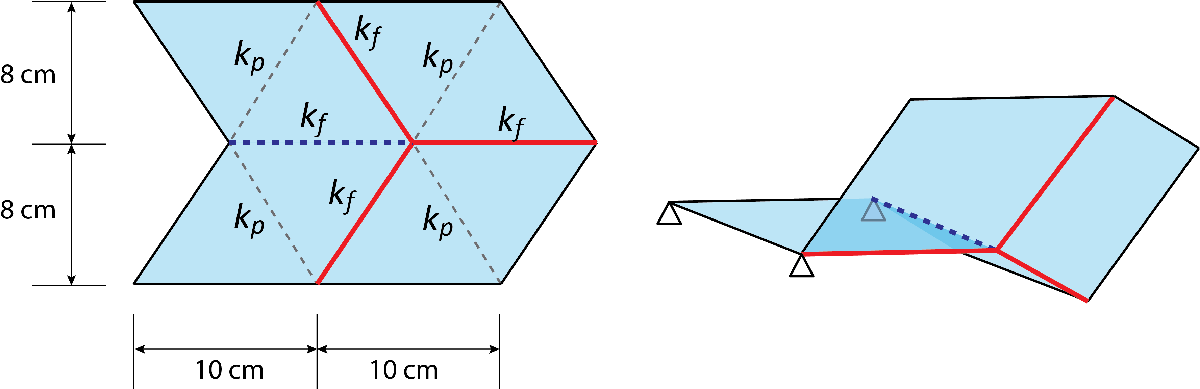

After we clear the memory, we define the mechanical properties of the Miura origami using the following script. The model we will use to simulate these origami assemblages is called "bar and hinge" model. In these bar and hinge models, the stretching and shearing of origami panels are captured using the bar elements, while the bending of origami panels and folding of origami creases are captured using the four node rotational spring elements. The four node rotational spring element is just like the three node rotational spring but with one extra node. With the additional node, this rotational spring can capture the folding anble between two triangle plate. We will learn the theory about the development of this triangle  in Section 12.

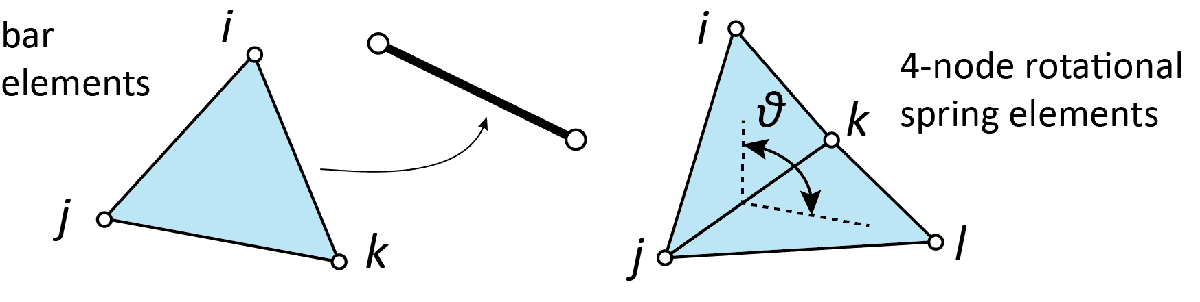

The bar and hinge model for simulation of origami is created back in 2011 by the paper by Mark Schenk and Simon D Guest published in origami^5. You can find this paper in the following link:

[http://www-g.eng.cam.ac.uk/advancedstructures/files/pdf/schenk2010.pdf](http://www-g.eng.cam.ac.uk/advancedstructures/files/pdf/schenk2010.pdf)

Another great reference for bar and hinge models is the paper by Ke Liu and Gaucio Paulino in 2017, where they demonstrated a robust nonlinear solution method and provided an implementation package for the bar and hinge model. 

[https://royalsocietypublishing.org/doi/full/10.1098/rspa.2017.0348](https://royalsocietypublishing.org/doi/full/10.1098/rspa.2017.0348)

After these works, the bar and hinge models have become a popular method to simulate the behaviors of active origami. Mark, Evgueni, and Myself have written a review paper on origami simulation, covering much more methods for simulating the behaviors of origami systems, which may also be of interests to some of you. 

[https://doi.org/10.1115/1.4055031](https://doi.org/10.1115/1.4055031)

Finally, before moving on to discuss more about mechanical origami simulation, I do hope to talk more about some of the very early works (almost forgotten by the field) on mechanical simulation of origami. Back in the 1970s. More specifically the work by Resch and Christiansen uses the triangle elements, bar elements, and four point rotational spring elements to simulate the behaviors of origami inpired foldable plates. Despite being a genius work, because of the lack of online access and being way ahead of the time, this paper is unfortunately not well recognized in our field. If you hope to get a copy, you can email me and I will be happy to share a photocopied version I got with you. 

Resch, R., Christiansen, H.N., **1971**. Kinematic folded plate system.* In Proceedings of IASS Symposium on Folded Plates and Prismatic Structures*, ed R. Krapfenbauer, IASS, Vienna, Austria.

Here, we will first work on the Miura origami unit using the bar and hinge model. Latter, I hope to demonstrate you how we can build a tirangle element to recreate the Resch and Christiansen paper. Both models are great lumped parameter models (simplifed mechanical model, coarse finite elements, or whatever names you want to use) for deployable origami systems, because they can capture both the large deformation kinematics and the load carrying capability of active origami. 

To get started, we define the elements we want to use for this example and then set up the assembly:

% Initialize the class
bar=Vec_Elements_Bars;
rotSpr=Vec_Elements_RotSprings_4N;
node=Elements_Nodes;

% Set up assembly
assembly=Assembly_Origami();
assembly.node=node;
assembly.bar=bar;
assembly.rotSpr=rotSpr;

We next define the geometry of Miura origami. This Miura origami has a total of 9 node and in the flat configuration they are in the XY plane. 

node.coordinates_mat=[0,0,0;
                      0.1,0,0;
                      0.2,0,0; % Node 3
                      0.04,0.08,0;
                      0.14,0.08,0;
                      0.24,0.08,0; % Node 6
                      0,0.16,0;
                      0.1,0.16,0;
                      0.2,0.16,0]; % Node 9

We then set up the ploting function and plot the location of the node of this Miura origami. 

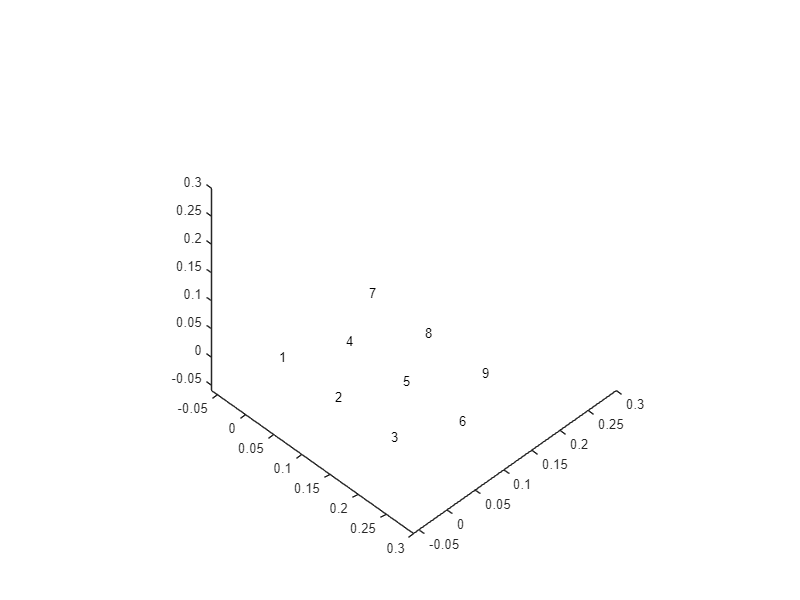

plots=Plot_Origami();
plots.displayRange=0.3;
plots.displayRangeRatio=0.2;
plots.assembly=assembly;

plots.Plot_Shape_Node_Number()

Everything looks good!

We next set up the panels. Each triangle panels are represented using 3 bars. The geometry representation of bars and the cross section areas for the bars can be derived using many different methods. Here, we adopt the method developed in the MERLIN2 paper by Liu and Paulino, where the cross-section area of the bar is calculated through matching the strain energy with the origami plate under uniform dilation. With this method the bar areas are:


$$A=\frac{2\mathrm{St}}{\left(1-v\right)\sum_i^N L_i }\;$$


where $v$ is the poisson's ratio, $S$ is the area of the origami panel, $t$ is the thickness of panels, and $L_i$ is the length of each bar elements. Further details can be found in the following paper

[https://paulino.princeton.edu/conferences/papers/18Liu_merlin2.pdf](https://paulino.princeton.edu/conferences/papers/18Liu_merlin2.pdf)

Let's work out the equation in the code.

% Define the material properties of the panel
E=10*10^6;  % Young's modulus 10MPa
v=0.3; % Poisson's Ratio 0.3
t=1*10^-3; % Thicknes 1mm

% Here the surface area of the origami is:
S=0.1*0.08*4;

% total bar length of the system is:
L_sum=6*0.1+6*(sqrt(0.08^2+0.04^2))+4*(sqrt(0.08^2+0.06^2));

% Find the bar area:
bar_A=(2*S*t)/(1-v)/(L_sum);

% set up bars
bar.node_ij_mat=[1 2;
                 2 3;
                 4 5;
                 5 6;
                 7 8;
                 8 9;
                 1 4;
                 2 5;
                 3 6;
                 4 7;
                 5 8;
                 6 9;
                 2 4;
                 4 8;
                 3 5;
                 5 9];

bar.E_vec=E*ones(16,1);
bar.A_vec=bar_A*ones(16,1);

Please note that here we are applying the equations to the full origami rather than to just a single panel here. In the MERLIN2 paper, the equation is applied to the each of the panels to support origami patterns with drastically different panels. This is mostly ok because the Miura origami we want to simulate has repeating panels. 

After defining the bars, we define the rotational springs. We assume that the creases' folding stiffness is $k_f =0\ldotp 00001\frac{N\cdot m}{m}$ and assume the panel bending stiffness is 1000 times the folding stiffness so $k_p =0\ldotp 01\frac{N\cdot m}{\;m}$.  

Every rotational spring has four node as shown in the following figure. Based on the four nodal coordinates (node i, j, k, and l), we can calcualte the $\theta \;$angle between the two triangles. This representation can capture the origami folding very well. A more detailed introduction of this element can be found in Section 09. 

% Define the stiffness parameter of the structure
k_f=0.00001;
k_p=0.01;

% Springs for the panel bending
rotSpr.node_ijkl_mat=[1 2 4 5;
                      2 3 5 6;
                      7 4 8 5;
                      8 5 9 6];

% Springs for the crease folding
rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                      4 2 5 3;
                      3 5 6 9;
                      4 5 8 9;
                      2 4 5 8];

% Spring stiffness
rotSpr.rot_spr_K_vec=ones(8,1);
rotSpr.rot_spr_K_vec(1:4)=rotSpr.rot_spr_K_vec(1:4)*k_p;
rotSpr.rot_spr_K_vec(5:8)=rotSpr.rot_spr_K_vec(5:8)*k_f;

Finally, we plot the elements for inspection. 

To give our origami model more origami look, we hope to further define the panels for visual effects. 

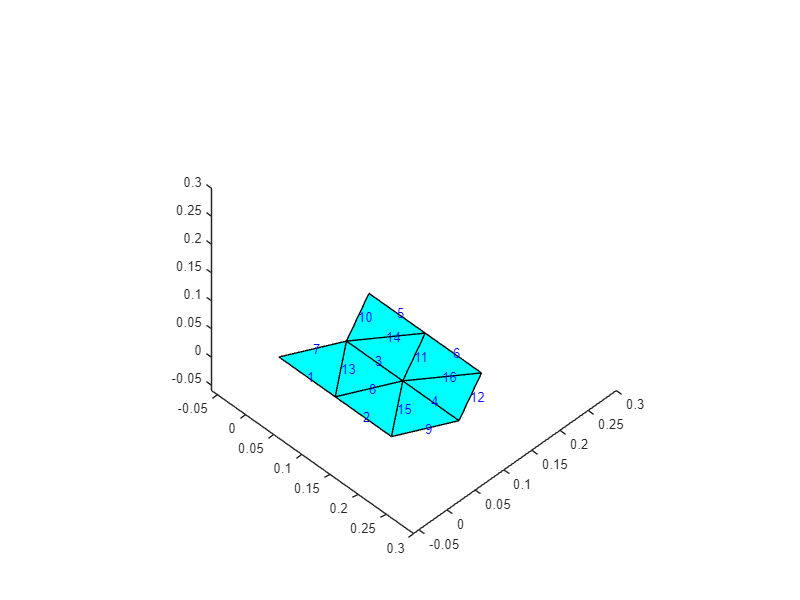

% Add panel information
plots.panelConnection{1}=[1 2 4];
plots.panelConnection{2}=[2 5 4];
plots.panelConnection{3}=[2 3 5];
plots.panelConnection{4}=[3 5 6];
plots.panelConnection{5}=[4 7 8];
plots.panelConnection{6}=[4 5 8];                     
plots.panelConnection{7}=[5 6 9];
plots.panelConnection{8}=[5 9 8];

%Plot for investigation
assembly.Initialize_Assembly();
plots.Plot_Shape_Bar_Number();

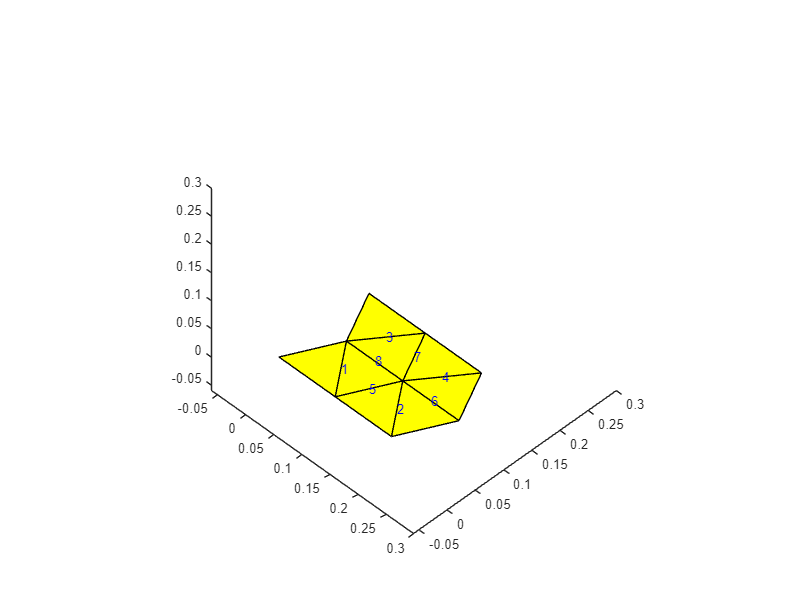

plots.Plot_Shape_Spr_Number()

Based on the visual result, we know that the code is working well.

Next we use the Newton-Raphson solver for four-node spring self folding. We set up the folding such that the target folding angle is $0\ldotp 8\pi \;$ away from the flat. Here we define the folding angle at flat as 180 degree or $\phi =\pi \ldotp$ With this assumption, the mountain Fold is defined to be smaller than $\pi \;$and the valley folds are bigger than $\pi$. 

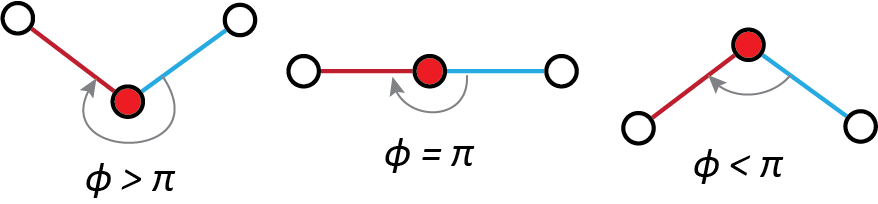

sf=Solver_NR_Folding_4N;
sf.assembly=assembly;
sf.supp=[1,1,1,1;
         2,1,1,1;
         4,1,1,1;];

% Define the target folding angle
foldAngle=0.8*pi;

% Please note that fold 8 is a mountain fold while 
% fold 5 6 7 are valley folds
sf.targetRot=assembly.rotSpr.theta_current_vec;
sf.targetRot(8)=sf.targetRot(8)-foldAngle;
sf.targetRot(5)=sf.targetRot(5)+foldAngle;
sf.targetRot(6)=sf.targetRot(6)+foldAngle;
sf.targetRot(7)=sf.targetRot(7)+foldAngle;

% Solver parameters
sf.increStep=50;
sf.tol=10^-6;
sf.iterMax=50;

After setting up the solver, we can solve for the folding history of this Miura origami unit. The deformed shape is nexted plotted.

Uhis=sf.Solve();

Self Assemble Analysis StartIcrement = 1
	Iteration = 1, R = 2.362301e-05 
	Iteration = 2, R = 2.786401e+00 
	Iteration = 3, R = 7.778703e-03 
	Iteration = 4, R = 1.015083e-05 
	Iteration = 5, R = 6.214674e-06 
	Iteration = 6, R = 4.583470e-09 
Icrement = 2
	Iteration = 1, R = 2.362177e-05 
	Iteration = 2, R = 2.791998e+00 
	Iteration = 3, R = 7.780033e-03 
	Iteration = 4, R = 4.298539e-05 
	Iteration = 5, R = 4.509987e-06 
	Iteration = 6, R = 9.304706e-09 
Icrement = 3
	Iteration = 1, R = 2.361806e-05 
	Iteration = 2, R = 2.800696e+00 
	Iteration = 3, R = 7.784866e-03 
	Iteration = 4, R = 8.814397e-05 
	Iteration = 5, R = 2.682776e-06 
	Iteration = 6, R = 3.051170e-08 
Icrement = 4
	Iteration = 1, R = 2.361224e-05 
	Iteration = 2, R = 2.812650e+00 
	Iteration = 3, R = 7.800710e-03 
	Iteration = 4, R = 1.355209e-04 
	Iteration = 5, R = 1.178051e-06 
	Iteration = 6, R = 4.457251e-08 
Icrement = 5
	Iteration = 1, R = 2.360316e-05 
	Iteration = 2, R = 2.827925e+00 
	Iteration = 3, R = 7.8

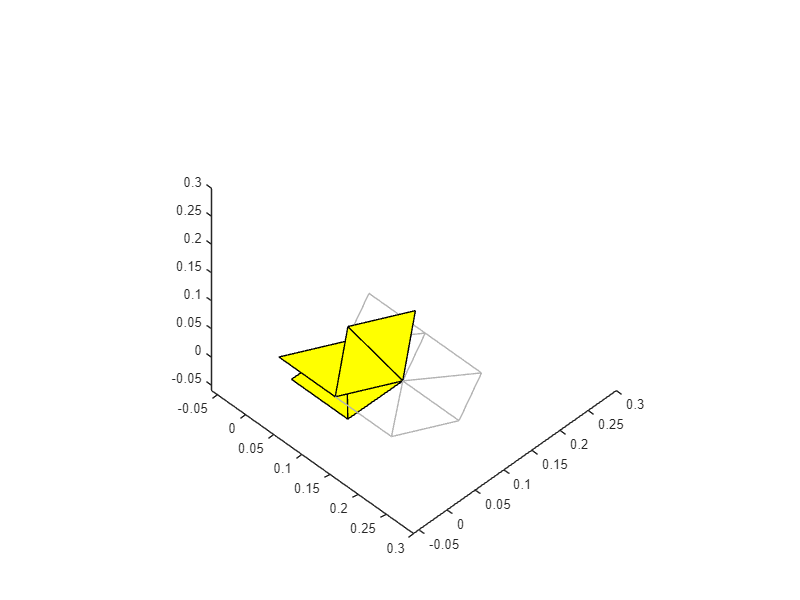

plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)));

We also hope to generate an animation of the full deployment process. This is done with the following code. We can now check out the generated GIF figure for the animation. 

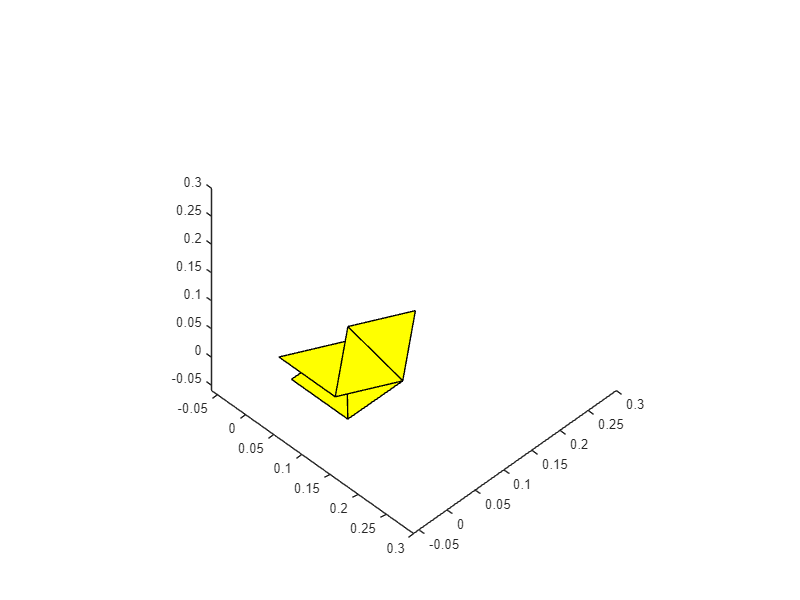

plots.fileName='Miura_Unit_Folding.gif';
plots.Plot_Deformed_His(Uhis);

The generated GIF is embeded here in the live script:

## 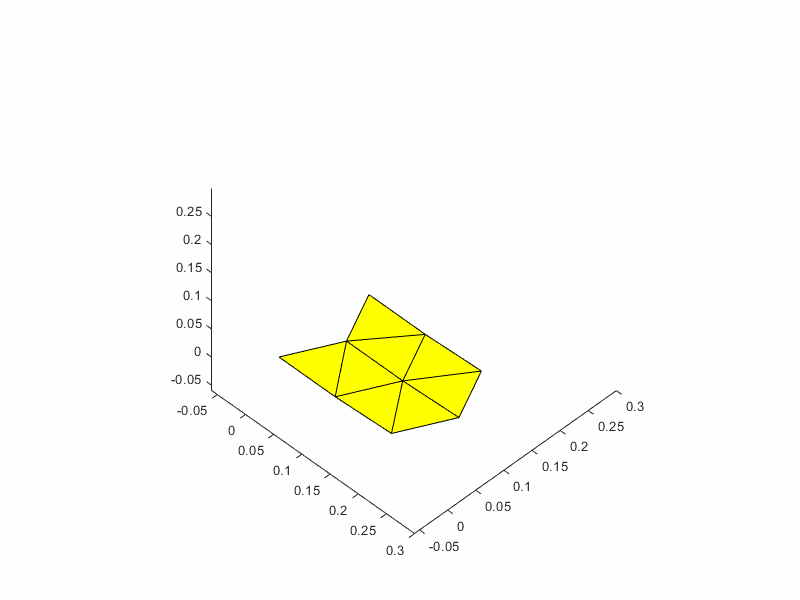

#### **Practice Problems:**

To practice, please consider further working out the following problems. 

#### **Problem 01**

Can you make a simulation of a full Miura origami sheet with 2*2 units?